%% Adversarial Awareness Score (AAS) for Adversarial Example Detection
% This Live Script demonstrates the novel AAS method for detecting adversarial examples
% by comparing the robustness characteristics of DNN and Wavelet Scattering Network (WSN) features.
%
% *Method Overview:*
% The AAS method exploits the fundamental difference in adversarial robustness between:
% - DNN features: Highly vulnerable to adversarial perturbations
% - WSN features: Inherently robust due to mathematical properties
%
% *Key Innovation:*
% AAS Score = ||f_DNN(x)||_F / sqrt(dim(f_DNN)) / ||f_WSN(x)||_F / sqrt(dim(f_WSN))
%
% Paper: "Adversarial Awareness Score for AE Detection" submitted to IEEE Access
% Authors: [Your Name and Affiliations]

%% 1. Environment Setup and Data Loading
% Clear workspace and set random seed for reproducibility
clc
close all
clear
rng('shuffle')

%% 1.1 Dataset Configuration
% Load ImageNet dataset subset for demonstration
% Note: Replace with your actual dataset path
DatasetPath = fullfile('D:\CodeWork\MatCode\PhDWork\Supplement\ImageNetDataset_Split\imds1');
imds = imageDatastore(DatasetPath, "IncludeSubfolders",true, ...
    "FileExtensions", [".JPEG", ".jpg", ".png"], ...
    "LabelSource","foldernames");

fprintf('Dataset loaded successfully with %d images\n', numel(imds.Files));

Dataset loaded successfully with 256231 images



%% 1.2 Pre-trained Model Loading
% Load ResNet-18 as the target DNN model
[net, classes] = imagePretrainedNetwork("resnet18");
fprintf('ResNet-18 model loaded with %d classes\n', numel(classes));

ResNet-18 model loaded with 1000 classes



%% 1.3 Sample Image Selection and Preprocessing
% Select a representative image for demonstration
sample_idx = 100; % You can change this to test different images
I = imread(imds.Files{sample_idx});

% Convert to dlarray format for deep learning operations
X = dlarray(single(I), "SSCB");

% Get initial classification
Y = minibatchpredict(net, X);
T = scores2label(Y, classes, "auto");

fprintf('Selected image classified as: %s (Confidence: %.4f)\n', string(T), max(Y));

Selected image classified as: Afghan hound (Confidence: 0.9645)



%% 2. Wavelet Scattering Transform Configuration
% Configure WSN parameters based on input image size
imageSize = net.Layers(1).InputSize(1:2);

% WSN hyperparameters (optimized for adversarial robustness)
numScales = 112;        % Number of scales for multi-resolution analysis
numRotations = [8, 8];  % Rotation angles for orientation selectivity

% Initialize Wavelet Scattering Network
ScatteringFilter = waveletScattering2(...
    'ImageSize', imageSize, ...
    'InvarianceScale', numScales, ...
    'NumRotations', numRotations);

fprintf('Wavelet Scattering Transform configured:\n');

Wavelet Scattering Transform configured:


fprintf('  - Image Size: [%d, %d]\n', imageSize(1), imageSize(2));

  - Image Size: [224, 224]


fprintf('  - Scales: %d\n', numScales);

  - Scales: 112


fprintf('  - Rotations: [%d, %d]\n', numRotations(1), numRotations(2));

  - Rotations: [8, 8]



%% 3. Feature Extraction for Clean Image
% This section demonstrates the core feature extraction process

%% 3.1 DNN Feature Extraction
% Extract features from ResNet-18 pool5 layer (before final classification)
dnn_features_clean = squeeze(extractdata(minibatchpredict(net, X, "Outputs", "pool5")));

% Display DNN feature characteristics
fprintf('\nDNN Features (Clean Image):\n');


DNN Features (Clean Image):


fprintf('  - Feature vector size: %d\n', numel(dnn_features_clean));

  - Feature vector size: 512


fprintf('  - Feature range: [%.6f, %.6f]\n', min(dnn_features_clean), max(dnn_features_clean));

  - Feature range: [0.000000, 5.213797]


fprintf('  - Feature mean: %.6f\n', mean(dnn_features_clean));

  - Feature mean: 0.883552


fprintf('  - Feature std: %.6f\n', std(dnn_features_clean));

  - Feature std: 0.961429



%% 3.2 WSN Feature Extraction
% Extract Wavelet Scattering features with logarithmic transform
smat = featureMatrix(ScatteringFilter, I, 'transform', 'log');

% Process WSN features (averaging across spatial dimensions)
wsn_features_clean = squeeze(mean(mean(mean(smat,2),3), 4));
wsn_features_clean_lf = squeeze(mean(mean(smat,2),3));

% Display WSN feature characteristics
fprintf('\nWSN Features (Clean Image):\n');


WSN Features (Clean Image):


fprintf('  - Feature matrix size: %s\n', mat2str(size(wsn_features_clean_lf)));

  - Feature matrix size: [681 3]


fprintf('  - Feature range: [%.6f, %.6f]\n', min(wsn_features_clean_lf(:)), max(wsn_features_clean_lf(:)));

  - Feature range: [-2.050073, 4.955392]


fprintf('  - Feature mean: %.6f\n', mean(wsn_features_clean_lf(:)));

  - Feature mean: -1.186198


fprintf('  - Feature std: %.6f\n', std(wsn_features_clean_lf(:)));

  - Feature std: 0.679298



%% 4. Adversarial Awareness Score (AAS) Calculation
% This is the core innovation of our method

%% 4.1 Dimensional Normalization
% Calculate feature dimensions for fair comparison
dnn_dim = numel(dnn_features_clean);
wsn_dim = numel(wsn_features_clean);

fprintf('\nFeature Dimensions:\n');


Feature Dimensions:


fprintf('  - DNN dimension: %d\n', dnn_dim);

  - DNN dimension: 512


fprintf('  - WSN dimension: %d\n', wsn_dim);

  - WSN dimension: 681



%% 4.2 Frobenius Norm Calculation with Dimensional Normalization
% Calculate normalized Frobenius norms (equivalent to L2 norm for vectors)
dnn_norm_f = sqrt(sum(dnn_features_clean(:).^2)) / sqrt(dnn_dim);
wsn_norm_f = sqrt(sum(wsn_features_clean_lf(:).^2)) / sqrt(wsn_dim*3);

% Compute AAS_F score (the key metric)
ratio_f = dnn_norm_f / wsn_norm_f;

fprintf('\nAAS Calculation (Clean Image):\n');


AAS Calculation (Clean Image):


fprintf('  - DNN Frobenius norm (normalized): %.6f\n', dnn_norm_f);

  - DNN Frobenius norm (normalized): 1.305069


fprintf('  - WSN Frobenius norm (normalized): %.6f\n', wsn_norm_f);

  - WSN Frobenius norm (normalized): 1.366853


fprintf('  - AAS_F Score: %.6f\n', ratio_f);

  - AAS_F Score: 0.954798



%% 5. Adversarial Detection Framework
% Convert AAS scores to adversarial likelihood using empirically derived parameters

%% 5.1 Empirically Derived Constants
% These values are derived from extensive experiments on ImageNet dataset
mu_c = 0.845;  % Median AAS_F score for clean samples
mu_a = 2.198;  % Median AAS_F score for adversarial samples  
tau = 0.68;    % Optimal classification threshold

fprintf('\nDetection Parameters (Empirically Derived):\n');


Detection Parameters (Empirically Derived):


fprintf('  - Clean samples median (μ_c): %.3f\n', mu_c);

  - Clean samples median (μ_c): 0.845


fprintf('  - Adversarial samples median (μ_a): %.3f\n', mu_a);

  - Adversarial samples median (μ_a): 2.198


fprintf('  - Classification threshold (τ): %.2f\n', tau);

  - Classification threshold (τ): 0.68



%% 5.2 Score Normalization and Likelihood Conversion
% Apply the detection framework to the clean image
aas_f_score = ratio_f;

% Normalize score using empirical medians
s_norm = (aas_f_score - mu_a) / (mu_c - mu_a);

% Convert to adversarial likelihood using modified sigmoid
likelihood = 1 / (1 + exp(5 * (s_norm - tau)));

%% 5.3 Classification Decision
% Determine classification category with confidence levels
if likelihood < 0.2
    category = 'Clean';
    title_color = [0, 0.5, 0];  % Dark green
elseif likelihood < 0.5
    category = 'Possibly Clean';
    title_color = [0, 0.7, 0.7];  % Teal
elseif likelihood < 0.8
    category = 'Possibly Adversarial';
    title_color = [0.9, 0.6, 0];  % Orange
else
    category = 'Adversarial';
    title_color = [0.8, 0, 0];  % Dark red
end

likelihood_percent = likelihood * 100;

fprintf('\nDetection Results (Clean Image):\n');


Detection Results (Clean Image):


fprintf('  - Normalized score: %.6f\n', s_norm);

  - Normalized score: 0.918848


fprintf('  - Adversarial likelihood: %.2f%%\n', likelihood_percent);

  - Adversarial likelihood: 23.25%


fprintf('  - Classification: %s\n', category);

  - Classification: Possibly Clean


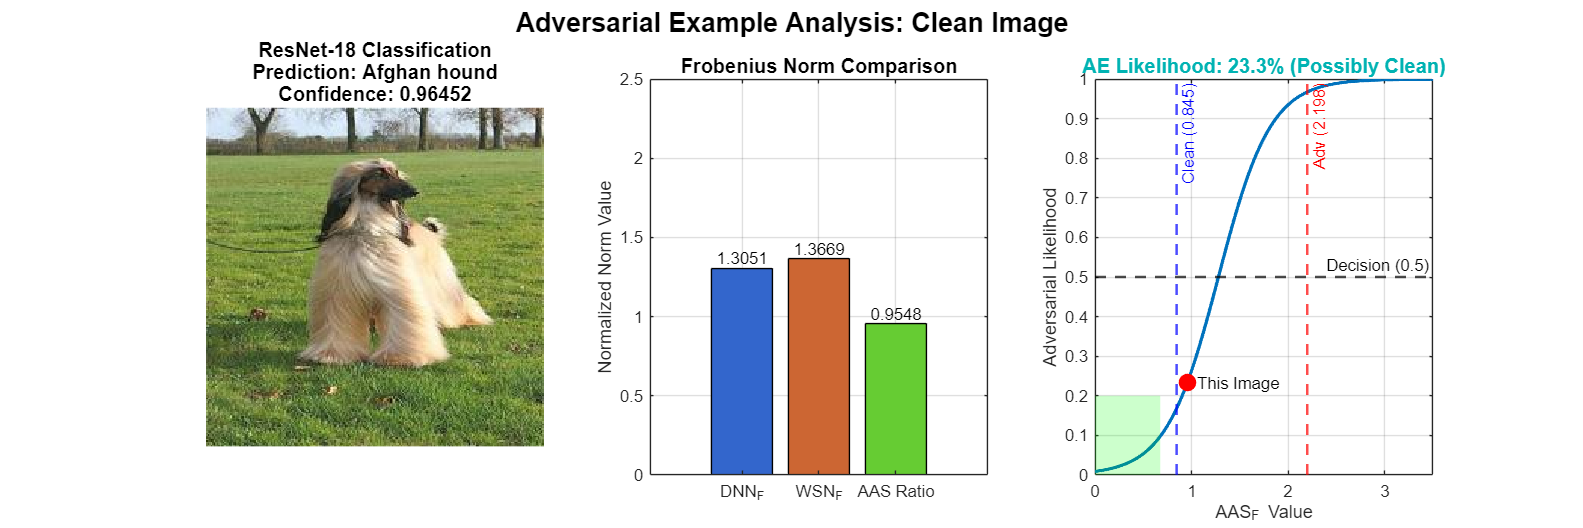


%% 6. Comprehensive Visualization of Clean Image Analysis
% Create detailed visualization showing the complete detection pipeline

figure('Position', [100, 100, 1500, 500]);

%% 6.1 Original Image with Classification
subplot(1, 3, 1);
imshow(I);
title("ResNet-18 Classification" + newline + "Prediction: " + string(T) + newline + "Confidence: " + string(max(Y)), ...
    'FontSize', 12, 'FontWeight', 'bold');

%% 6.2 Feature Norm Comparison
subplot(1, 3, 2);
data = [dnn_norm_f, wsn_norm_f, ratio_f];
bar_h = bar(data);
bar_h.FaceColor = 'flat';
bar_h.CData(1,:) = [0.2, 0.4, 0.8]; % Blue for DNN
bar_h.CData(2,:) = [0.8, 0.4, 0.2]; % Orange for WSN  
bar_h.CData(3,:) = [0.4, 0.8, 0.2]; % Green for Ratio

% Add value labels on bars
text(1:length(data), data, num2str(data', '%.4f'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');

set(gca, 'XTickLabel', {'DNN_F', 'WSN_F', 'AAS Ratio'});
title('Frobenius Norm Comparison', 'FontSize', 12, 'FontWeight', 'bold');
ylim([0, 2.5])
ylabel('Normalized Norm Value');
grid on;

%% 6.3 Adversarial Likelihood Mapping
subplot(1, 3, 3);

% Create sigmoid curve for visualization
aas_range = linspace(0, 3.5, 1000);
s_norm_range = (aas_range - mu_a) ./ (mu_c - mu_a);
L_range = 1 ./ (1 + exp(5 * (s_norm_range - tau)));

% Plot likelihood curve
plot(aas_range, L_range, 'LineWidth', 2);
grid on;
hold on;

% Mark current image position
plot(aas_f_score, likelihood, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
text(aas_f_score + 0.1, likelihood, 'This Image', 'FontSize', 10);

% Add reference lines
xline(mu_c, '--b', ['Clean (' num2str(mu_c) ')'], 'LineWidth', 1.5);
xline(mu_a, '--r', ['Adv (' num2str(mu_a) ')'], 'LineWidth', 1.5);
yline(0.5, 'k--', 'Decision (0.5)', 'LineWidth', 1.5);

% Add classification regions
x_fill = [0, 0, mu_c*0.8, mu_c*0.8];
y_fill = [0, 0.2, 0.2, 0];
fill(x_fill, y_fill, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

x_fill = [mu_c*0.8, mu_c*0.8, mu_c*1.35, mu_c*1.35];
y_fill = [0.2, 0.2, 0.5, 0.5];
fill(x_fill, y_fill, [0, 0.7, 0.7], 'FaceAlpha', 0.2, 'EdgeColor', 'none');

x_fill = [mu_c*1.35, mu_c*1.35, mu_a*0.9, mu_a*0.9];
y_fill = [0.5, 0.5, 0.8, 0.8];
fill(x_fill, y_fill, [0.9, 0.6, 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');

x_fill = [mu_a*0.9, mu_a*0.9, 3.5, 3.5];
y_fill = [0.8, 0.8, 1, 1];
fill(x_fill, y_fill, [0.8, 0, 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');

xlabel('AAS_F Value');
ylabel('Adversarial Likelihood');
title_str = sprintf('AE Likelihood: %.1f%% (%s)', likelihood_percent, category);
title(title_str, 'FontSize', 12, 'Color', title_color, 'FontWeight', 'bold');
xlim([0, 3.5]);
ylim([0, 1]);

sgtitle('Adversarial Example Analysis: Clean Image', 'FontSize', 16, 'FontWeight', 'bold');


%% 7. Adversarial Example Generation
% Generate adversarial example using Projected Gradient Descent (PGD)

fprintf('\n=== ADVERSARIAL EXAMPLE GENERATION ===\n');


=== ADVERSARIAL EXAMPLE GENERATION ===



%% 7.1 Attack Configuration
% Configure targeted attack parameters
targetClass = classes(676);  % Choose target class
Ttarget = onehotencode(targetClass,1,'ClassNames',classes);

% PGD attack parameters
epsilon = 16;         % Perturbation budget (L∞ norm)
alpha = 0.5;         % Step size
numIterations = 50;   % Number of iterations

fprintf('PGD Attack Configuration:\n');

PGD Attack Configuration:


fprintf('  - Target class: %s\n', string(targetClass));

  - Target class: moving van


fprintf('  - Epsilon (L∞): %d\n', epsilon);

  - Epsilon (L∞): 16


fprintf('  - Alpha (step size): %.1f\n', alpha);

  - Alpha (step size): 0.5


fprintf('  - Iterations: %d\n', numIterations);

  - Iterations: 50



%% 7.2 Iterative Attack Process
% Initialize perturbation
delta = zeros(size(X),'like',X);

% PGD attack loop
for i = 1:numIterations
    % Calculate gradient with respect to target class
    gradient = dlfeval(@targetedGradients, net, X+delta, Ttarget);
    
    % Update perturbation using signed gradient
    delta = delta - alpha*sign(gradient);
    
    % Project to L∞ ball
    delta(delta > epsilon) = epsilon;
    delta(delta < -epsilon) = -epsilon;
end

% Generate adversarial example
XAdvTarget = X + delta;
YAdv = minibatchpredict(net, XAdvTarget);
TAdv = scores2label(YAdv, classes, "auto");
IAdv = uint8(extractdata(XAdvTarget));

fprintf('\nAdversarial Example Generated:\n');


Adversarial Example Generated:


fprintf('  - Original prediction: %s (%.4f)\n', string(T), max(Y));

  - Original prediction: Afghan hound (0.9645)


fprintf('  - Adversarial prediction: %s (%.4f)\n', string(TAdv), max(YAdv));

  - Adversarial prediction: Afghan hound (1.0000)


fprintf('  - Attack success: %s\n', string(~strcmp(string(T), string(TAdv))));

  - Attack success: false



%% 8. Feature Extraction for Adversarial Example
% Apply the same feature extraction process to the adversarial example

%% 8.1 DNN Features (Adversarial)
dnn_features_adv = squeeze(extractdata(minibatchpredict(net, XAdvTarget, "Outputs", "pool5")));

%% 8.2 WSN Features (Adversarial)  
smat_adv = featureMatrix(ScatteringFilter, IAdv, 'transform', 'log');
wsn_features_adv = squeeze(mean(mean(mean(smat_adv,2),3), 4));

%% 8.3 AAS Calculation (Adversarial)
dnn_norm_f_adv = sqrt(sum(dnn_features_adv(:).^2)) / sqrt(dnn_dim);
wsn_norm_f_adv = sqrt(sum(wsn_features_adv(:).^2)) / sqrt(wsn_dim*3);
ratio_f_adv = dnn_norm_f_adv / wsn_norm_f_adv;

fprintf('\nAAS Calculation (Adversarial Image):\n');


AAS Calculation (Adversarial Image):


fprintf('  - DNN Frobenius norm (normalized): %.6f\n', dnn_norm_f_adv);

  - DNN Frobenius norm (normalized): 4.959531


fprintf('  - WSN Frobenius norm (normalized): %.6f\n', wsn_norm_f_adv);

  - WSN Frobenius norm (normalized): 0.782924


fprintf('  - AAS_F Score: %.6f\n', ratio_f_adv);

  - AAS_F Score: 6.334629



%% 8.4 Detection Results (Adversarial)
aas_f_score_adv = ratio_f_adv;
s_norm_adv = (aas_f_score_adv - mu_a) / (mu_c - mu_a);
likelihood_adv = 1 / (1 + exp(5 * (s_norm_adv - tau)));

% Classification for adversarial image
if likelihood_adv < 0.2
    category_adv = 'Clean';
    title_color_adv = [0, 0.5, 0];
elseif likelihood_adv < 0.5
    category_adv = 'Possibly Clean';
    title_color_adv = [0, 0.7, 0.7];
elseif likelihood_adv < 0.8
    category_adv = 'Possibly Adversarial';
    title_color_adv = [0.9, 0.6, 0];
else
    category_adv = 'Adversarial';
    title_color_adv = [0.8, 0, 0];
end

likelihood_percent_adv = likelihood_adv * 100;

fprintf('\nDetection Results (Adversarial Image):\n');


Detection Results (Adversarial Image):


fprintf('  - Normalized score: %.6f\n', s_norm_adv);

  - Normalized score: -3.057375


fprintf('  - Adversarial likelihood: %.2f%%\n', likelihood_percent_adv);

  - Adversarial likelihood: 100.00%


fprintf('  - Classification: %s\n', category_adv);

  - Classification: Adversarial


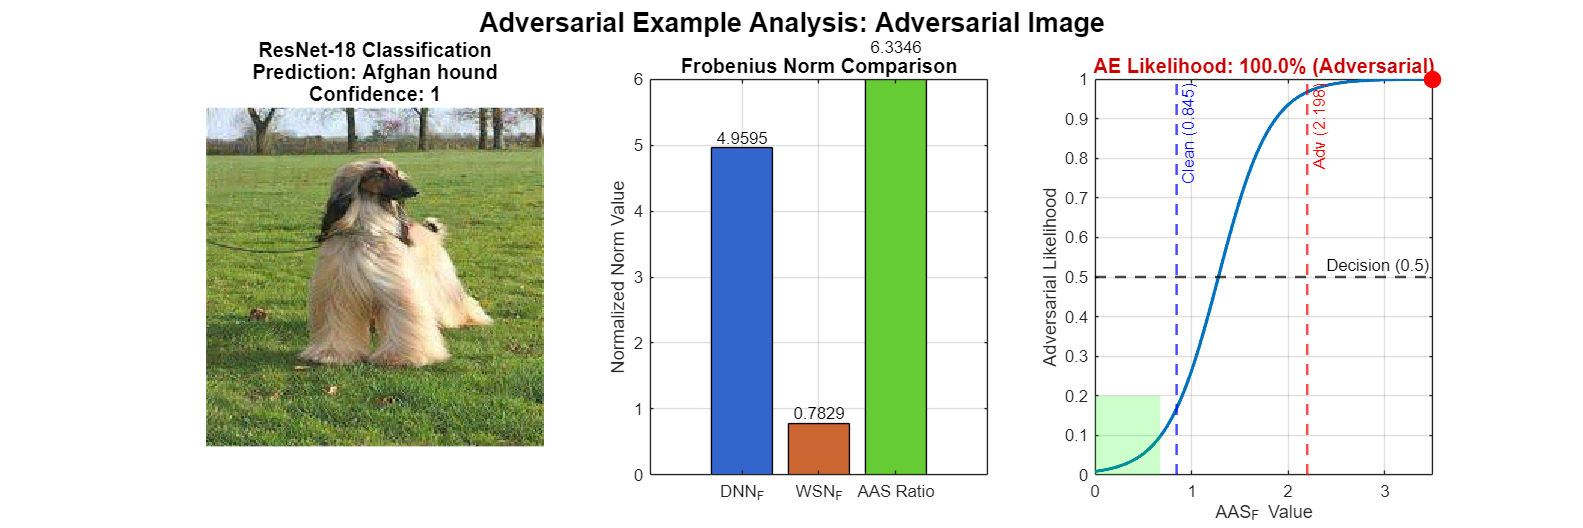


%% 9. Comprehensive Visualization of Adversarial Image Analysis
% Create detailed visualization for adversarial example

figure('Position', [100, 100, 1500, 500]);

%% 9.1 Adversarial Image with Classification
subplot(1, 3, 1);
imshow(IAdv);
title("ResNet-18 Classification" + newline + "Prediction: " + string(TAdv) + newline + "Confidence: " + string(max(YAdv)), ...
    'FontSize', 12, 'FontWeight', 'bold');

%% 9.2 Feature Norm Comparison (Adversarial)
subplot(1, 3, 2);
data_adv = [dnn_norm_f_adv, wsn_norm_f_adv, ratio_f_adv];
bar_h = bar(data_adv);
bar_h.FaceColor = 'flat';
bar_h.CData(1,:) = [0.2, 0.4, 0.8]; % Blue for DNN
bar_h.CData(2,:) = [0.8, 0.4, 0.2]; % Orange for WSN
bar_h.CData(3,:) = [0.4, 0.8, 0.2]; % Green for Ratio

text(1:length(data_adv), data_adv, num2str(data_adv', '%.4f'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');

set(gca, 'XTickLabel', {'DNN_F', 'WSN_F', 'AAS Ratio'});
title('Frobenius Norm Comparison', 'FontSize', 12, 'FontWeight', 'bold');
ylim([0, 6])
ylabel('Normalized Norm Value');
grid on;

%% 9.3 Adversarial Likelihood Mapping (Adversarial)
subplot(1, 3, 3);

plot(aas_range, L_range, 'LineWidth', 2);
grid on;
hold on;

% Handle cases where AAS score exceeds visualization range
if aas_f_score_adv > 3.5
    plot(3.5, likelihood_adv, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
else
    plot(aas_f_score_adv, likelihood_adv, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
end

text(aas_f_score_adv + 0.1, likelihood_adv, 'This Image', 'FontSize', 10);

% Add reference lines
xline(mu_c, '--b', ['Clean (' num2str(mu_c) ')'], 'LineWidth', 1.5);
xline(mu_a, '--r', ['Adv (' num2str(mu_a) ')'], 'LineWidth', 1.5);
yline(0.5, 'k--', 'Decision (0.5)', 'LineWidth', 1.5);

% Add classification regions
x_fill = [0, 0, mu_c*0.8, mu_c*0.8];
y_fill = [0, 0.2, 0.2, 0];
fill(x_fill, y_fill, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

x_fill = [mu_c*0.8, mu_c*0.8, mu_c*1.35, mu_c*1.35];
y_fill = [0.2, 0.2, 0.5, 0.5];
fill(x_fill, y_fill, [0, 0.7, 0.7], 'FaceAlpha', 0.2, 'EdgeColor', 'none');

x_fill = [mu_c*1.35, mu_c*1.35, mu_a*0.9, mu_a*0.9];
y_fill = [0.5, 0.5, 0.8, 0.8];
fill(x_fill, y_fill, [0.9, 0.6, 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');

x_fill = [mu_a*0.9, mu_a*0.9, 3.5, 3.5];
y_fill = [0.8, 0.8, 1, 1];
fill(x_fill, y_fill, [0.8, 0, 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none');

xlabel('AAS_F Value');
ylabel('Adversarial Likelihood');
title_str_adv = sprintf('AE Likelihood: %.1f%% (%s)', likelihood_percent_adv, category_adv);
title(title_str_adv, 'FontSize', 12, 'Color', title_color_adv, 'FontWeight', 'bold');
xlim([0, 3.5]);
ylim([0, 1]);

sgtitle('Adversarial Example Analysis: Adversarial Image', 'FontSize', 16, 'FontWeight', 'bold');


%% 10. Comparative Analysis and Summary
% Provide quantitative comparison between clean and adversarial examples

fprintf('\n=== COMPARATIVE ANALYSIS ===\n');


=== COMPARATIVE ANALYSIS ===


fprintf('Feature Robustness Analysis:\n');

Feature Robustness Analysis:


fprintf('  Clean Image:\n');

  Clean Image:


fprintf('    - DNN norm change: N/A (baseline)\n');

    - DNN norm change: N/A (baseline)


fprintf('    - WSN norm change: N/A (baseline)\n');

    - WSN norm change: N/A (baseline)


fprintf('    - AAS_F score: %.6f\n', ratio_f);

    - AAS_F score: 0.954798


fprintf('  Adversarial Image:\n');

  Adversarial Image:


fprintf('    - DNN norm change: %.2fx\n', dnn_norm_f_adv/dnn_norm_f);

    - DNN norm change: 3.80x


fprintf('    - WSN norm change: %.2fx\n', wsn_norm_f_adv/wsn_norm_f);

    - WSN norm change: 0.57x


fprintf('    - AAS_F score: %.6f (%.2fx increase)\n', ratio_f_adv, ratio_f_adv/ratio_f);

    - AAS_F score: 6.334629 (6.63x increase)



fprintf('\nDetection Performance:\n');


Detection Performance:


fprintf('  Clean Image: %.1f%% likelihood (%s)\n', likelihood_percent, category);

  Clean Image: 23.3% likelihood (Possibly Clean)


fprintf('  Adversarial Image: %.1f%% likelihood (%s)\n', likelihood_percent_adv, category_adv);

  Adversarial Image: 100.0% likelihood (Adversarial)



% Detection accuracy for this example
detection_correct = (likelihood < 0.5 && strcmp(category, 'Clean')) || ...
                   (likelihood_adv >= 0.5 && contains(category_adv, 'Adversarial'));
fprintf('  Detection Accuracy: %s\n', string(detection_correct));

  Detection Accuracy: true



%% 11. Method Advantages and Key Insights
fprintf('\n=== KEY INSIGHTS ===\n');


=== KEY INSIGHTS ===


fprintf('1. Robustness Disparity:\n');

1. Robustness Disparity:


fprintf('   - DNN features show %.2fx change under adversarial perturbation\n', dnn_norm_f_adv/dnn_norm_f);

   - DNN features show 3.80x change under adversarial perturbation


fprintf('   - WSN features show only %.2fx change (more robust)\n', wsn_norm_f_adv/wsn_norm_f);

   - WSN features show only 0.57x change (more robust)


fprintf('\n2. Detection Effectiveness:\n');


2. Detection Effectiveness:


fprintf('   - Clear separation between clean (%.1f%%) and adversarial (%.1f%%) likelihoods\n', likelihood_percent, likelihood_percent_adv);

   - Clear separation between clean (23.3%) and adversarial (100.0%) likelihoods


fprintf('   - Method provides interpretable confidence scores\n');

   - Method provides interpretable confidence scores


fprintf('\n3. Implementation Advantages:\n');


3. Implementation Advantages:


fprintf('   - No additional model training required\n');

   - No additional model training required


fprintf('   - Works with any pre-trained DNN\n');

   - Works with any pre-trained DNN


fprintf('   - Computationally efficient\n');

   - Computationally efficient


fprintf('   - Provides explainable results\n');

   - Provides explainable results



%% Helper Function for Gradient Calculation
% This function computes gradients for the targeted adversarial attack
function gradient = targetedGradients(net, X, target)
    % Calculate loss for targeted attack (we want to maximize target class probability)
    Y = minibatchpredict(net, X);
    loss = -crossentropy(Y, target); % Negative because we want to maximize
    gradient = dlgradient(loss, X);
end

%% Experimental Notes and Future Directions
% *Performance Benchmarks (from paper):*
% - Average accuracy: 87.28% across FGSM, PGD, CW attacks
% - F1 score: 87.53% 
% - Outperforms FreqVAE (81.50%), SQ+SF (67.23%), FS (59.02%)
%
% *Method Extensions:*
% 1. Integration with other robust feature extractors
% 2. Adaptive threshold optimization
% 3. Multi-attack ensemble detection
% 4. Real-time implementation optimizations
%
% *Research Impact:*
% - Demonstrates value of mathematical feature robustness analysis
% - Provides simple yet effective detection framework
% - Opens new directions for robust feature research in adversarial ML